# 第5章 数字滤波器结构

## 5.4 无限长单位脉冲响应数字滤波器设计

### 5.4.4 切比雪夫滤波器

#### `Ch5_4_5`

绘制巴特沃斯-切比雪夫滤波器特性$A\left(\Omega^2 \right)$比较图。

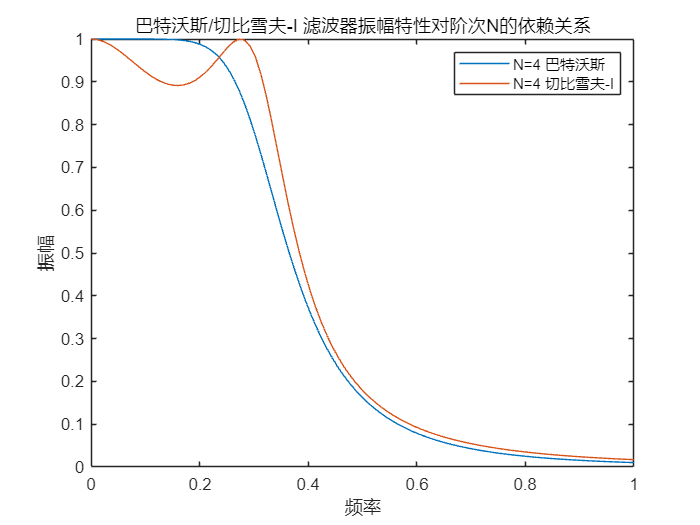

n = 4; str = ["N=4 巴特沃斯", "N=4 切比雪夫-I"];
%巴特沃斯
[z, p, k]=buttap(n);
[num,den] = zp2tf(z,p,k);
w = linspace(0, pi);        
h = freqs(num,den,w);
mag = abs(h)/abs(h(1));
plot(w/pi,mag);
hold on;   
%切比雪夫-I
Rp = 1; 
n = 1;
[z,p,k] = cheb1ap(n,Rp);       
[num,den] = zp2tf(z,p,k);     
w = linspace(0, pi);        
h = freqs(num,den,w);
max_h = h(1);

n = 3;
[z,p,k] = cheb1ap(n,Rp);       
[num,den] = zp2tf(z,p,k);     
w = linspace(0, pi);        
h = freqs(num,den,w);
mag = abs(h)/abs(max_h);
plot(w/pi,mag);

xlabel('频率'); ylabel('振幅'); 
title('巴特沃斯/切比雪夫-I 滤波器振幅特性对阶次N的依赖关系');
legend(str(1),str(2));